# Синтез цифровой системы управления

КУМС, ЛР №6

Кирбаба Денис R3438

#### Инициализация

load('var_30.mat')
To = 0.001;

#### Синтез модели

syms L_s R_s Cm_s Ce_s s J_s
syms u I Omega alpha di dOmega dalpha

eq(1) = L_s*di == u - R_s*I - Ce_s*Omega;
eq(2) = J_s*dOmega == Cm_s*I;
eq(3) = dalpha == Omega;
S = solve(eq, [di dOmega dalpha]);
disp(collect(S.di, [I Omega alpha u]))

$$\left(-\frac{R_{s}}{L_{s}}\right)\,\text{I}+\left(-\frac{{\mathrm{Ce}}_{s}}{L_{s}}\right)\,\Omega +\frac{u}{L_{s}}$$

disp(collect(S.dOmega, [I Omega alpha u]))

$$\frac{{\mathrm{Cm}}_{s}}{J_{s}}\,\text{I}$$

disp(collect(S.dalpha, [I Omega alpha u]))

$$\Omega$$

#### Модель вход-состояние-выход

A = [-R_s/L_s -Ce_s/L_s 0;...
    Cm_s/J_s 0 0;
    0 1 0];
B = [1/L_s; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

#### Передаточные функции

W = C*(s*eye(3)-A)^-1*B+D

$$W = \left(\begin{array}{c} \frac{J_{s}\,s}{J_{s}\,L_{s}\,s^{2}+J_{s}\,R_{s}\,s+{\mathrm{Ce}}_{s}\,{\mathrm{Cm}}_{s}}\\ \frac{{\mathrm{Cm}}_{s}}{J_{s}\,L_{s}\,s^{2}+J_{s}\,R_{s}\,s+{\mathrm{Ce}}_{s}\,{\mathrm{Cm}}_{s}} \end{array}\right)$$

#### Синтез регулятора контура тока

Настройка на линейный оптимум

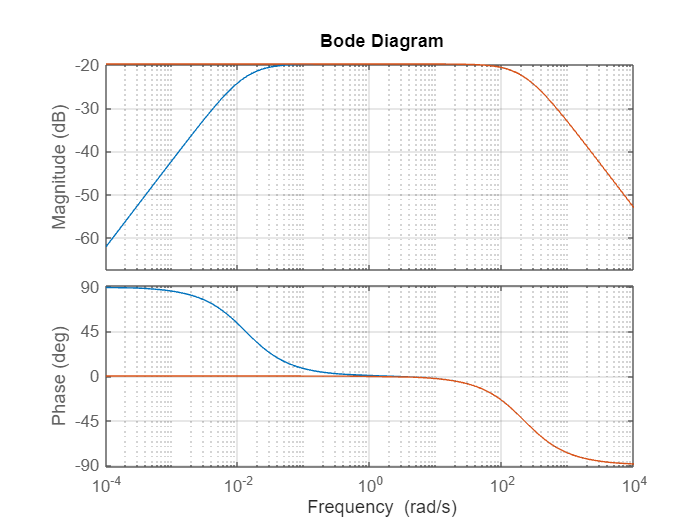

J = 1;
ob_cur_1 = tf([J 0],[J*L J*R Ce*Cm]);
ob_cur_2 = tf([1/R],[L/R 1]);

figure
bode(ob_cur_1)
hold on
grid on
bode(ob_cur_2)

Разница между этими ПФ в низкочастотной области (до 1 rad/s). Если частота среза контура тока >1 rad/s (постоянная времени настройки на линейный оптимум), то мы можем использовать вторую (упрощенную) ПФ. Если контур тока медленный (частота среза <1 rad/s), то при замене первой ПФ второй это будет сказываться на результате настройки.

Мы можем пренебречь обраной связью по противоЭДС когда у нас быстрый контур тока (частота среза >1 rad/s).

syms Tt_s Te_s Tz_s
Te_s = L_s/R_s;
Wtfobi = 1/R_s/((Te_s + Tz_s)*s + 1);
Wtfet = 1/Tt_s/s;
Wtfreg = collect(Wtfet/Wtfobi,s)

$$Wtfreg = \frac{\left(L_{s}+R_{s}\,{\mathrm{Tz}}_{s}\right)\,s+R_{s}}{{\mathrm{Tt}}_{s}\,s}$$

Tt = 0.003;
Tz = To/2 + To/1000;
crlp.Kp = (L+R*Tz)/Tt;
crlp.Ki = R/Tt;

Tmdl = 0.04;

warning off
SimOut = sim('lab6_current.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

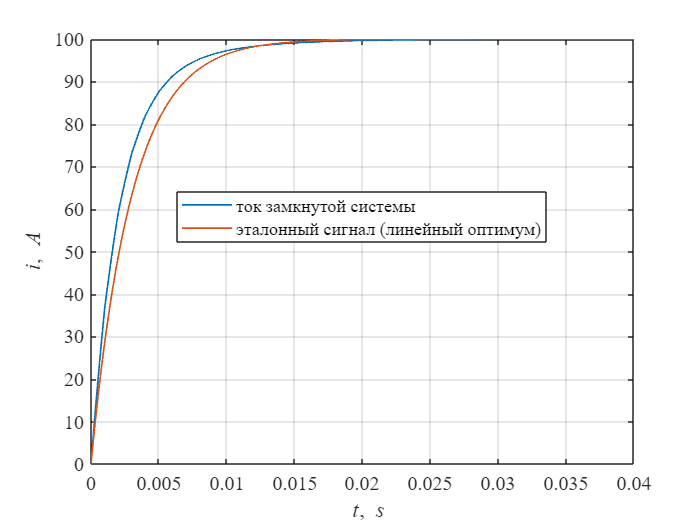

t = SimOut.i(:,1);
ic = SimOut.i(:,2);
ic_et = SimOut.i(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,ic,'LineWidth',1)
hold on
grid on
plot(t,ic_et,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\iti\rm,\it A')
legend('ток замкнутой системы','эталонный сигнал (линейный оптимум)','Location','best')

#### Определение момента инерции

Tmdl = 10;

warning off
SimOut = sim('lab6_inertia.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

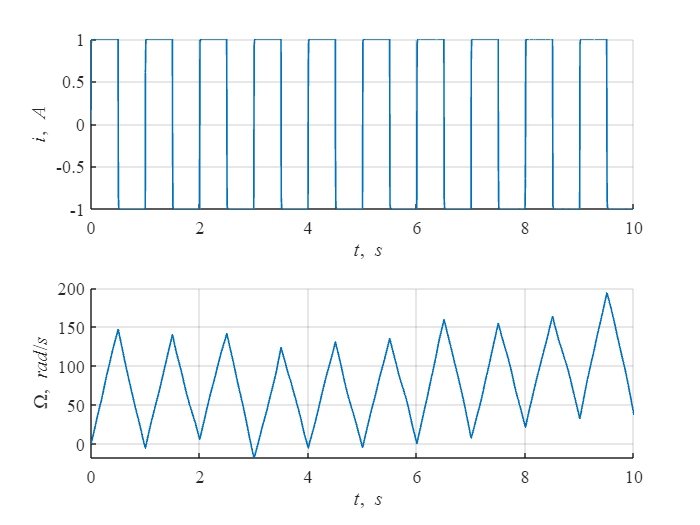

t = SimOut.i(:,1);
ic = SimOut.i(:,2);
wc = SimOut.i(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
hold on
grid on
plot(t,ic,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\iti\rm,\it A')

ax(2) = subplot(2,1,2);
hold on
grid on
plot(t,wc,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm,\it rad\rm/\its')

linkaxes(ax, 'x')

Мы подавали ток, а ток по сути пропорционален моменту и, соответственно, привод у нас то ускорялся, то замедлялся.

По этому графику определим момент инерции (нужно определить наклон функции Omega(t)).

for k = 1:20
    ind = (t > (k-1)*0.5) & (t < k*0.5);
    t_exp = t(ind);
    w_exp = wc(ind);
    i_exp = ic(ind);
    mc = mean(i_exp)*Cm;
    t1 = t_exp(1);
    t2 = t_exp(end);
    w1 = w_exp(1);
    w2 = w_exp(end);
    ec = (w2-w1)/(t2-t1);
    Jc(k) = mc/ec;
end
J = mean(Jc)

J = 0.0012

#### Синтез системы управления скоростью

J = 0.0012;
syms Tu_s
Wtfobsp = 1/((Tu_s)*s + 1)*Cm_s/J_s/s

$$Wtfobsp = \frac{{\mathrm{Cm}}_{s}}{J_{s}\,s\,\left({\mathrm{Tu}}_{s}\,s+1\right)}$$

Tu = Tt + Tz;

Эту ПФ объекта мы хотим настроить с помощью полиномиального регулятора

Сначала нужно определить порядок регулятора = {порядок ОУ} - 1 + {количество свободных интеграторов, которые будут присутствовать в регуляторе}

l = 2 - 1 + 1  % порядок регулятора

l = 2

syms b_2 b_1 b_0 a_1 
syms r_3 r_2 r_1 r_0
Wsplp = (b_2*s^2 + b_1*s + b_0)/(a_1*s + 1)/s  % по сути это ПИД-регулятор

$$Wsplp = \frac{b_{2}\,s^{2}+b_{1}\,s+b_{0}}{s\,\left(a_{1}\,s+1\right)}$$

Wcl = collect(Wtfobsp*Wsplp/(1 + Wtfobsp*Wsplp),s)

$$Wcl = \frac{\left({\mathrm{Cm}}_{s}\,b_{2}\right)\,s^{2}+\left({\mathrm{Cm}}_{s}\,b_{1}\right)\,s+{\mathrm{Cm}}_{s}\,b_{0}}{\left(J_{s}\,{\mathrm{Tu}}_{s}\,a_{1}\right)\,s^{4}+\left(J_{s}\,a_{1}+J_{s}\,{\mathrm{Tu}}_{s}\right)\,s^{3}+\left(J_{s}+{\mathrm{Cm}}_{s}\,b_{2}\right)\,s^{2}+\left({\mathrm{Cm}}_{s}\,b_{1}\right)\,s+{\mathrm{Cm}}_{s}\,b_{0}}$$

В числителе получается полином, который мы хотим привести к желаемому виду (заданному распределению корней (распределение Баттерворта, Чебышева, Ньютона, знаменатель какого-то оптимума, либо самим задать распределение корней))

% желаемый полином с желаемым распределением корней
% s^4 + r_3*s^3 + r_2*s^2 + r_1*s + r_0
eq(1) = (J_s*a_1 + J_s*Tu_s)/(J_s*Tu_s*a_1) == r_3;
eq(2) = (J_s + Cm_s*b_2)/(J_s*Tu_s*a_1) == r_2;
eq(3) = (Cm_s*b_1)/(J_s*Tu_s*a_1) == r_1;
eq(4) = Cm_s*b_0/(J_s*Tu_s*a_1) == r_0;

Sn = solve(eq, [b_2 b_1 b_0 a_1]);
disp(collect(Sn.b_2))

$$\frac{J_{s}\,{{\mathrm{Tu}}_{s}}^{2}}{{\mathrm{Cm}}_{s}\,\left({\mathrm{Tu}}_{s}\,r_{3}-1\right)}\,r_{2}-\frac{J_{s}}{{\mathrm{Cm}}_{s}}$$

disp(Sn.b_1)

$$\frac{J_{s}\,{{\mathrm{Tu}}_{s}}^{2}\,r_{1}}{{\mathrm{Cm}}_{s}\,\left({\mathrm{Tu}}_{s}\,r_{3}-1\right)}$$

disp(Sn.b_0)

$$\frac{J_{s}\,{{\mathrm{Tu}}_{s}}^{2}\,r_{0}}{{\mathrm{Cm}}_{s}\,\left({\mathrm{Tu}}_{s}\,r_{3}-1\right)}$$

disp(Sn.a_1)

$$\frac{{\mathrm{Tu}}_{s}}{{\mathrm{Tu}}_{s}\,r_{3}-1}$$

#### Расчет параметров регулятора

rp.poles = -[551-236*j 551+236*j 288-554*j 288+554*j];
rp.poly = poly(rp.poles);
r3 = rp.poly(2);
r2 = rp.poly(3);
r1 = rp.poly(4);
r0 = rp.poly(5);

b2 = ((J*Tu^2)/(Cm*(Tu*r3 - 1)))*r2 - J/Cm;
b1 = (J*Tu^2*r1)/(Cm*(Tu*r3 - 1));
b0 = (J*Tu^2*r0)/(Cm*(Tu*r3 - 1));
a1 = Tu/(Tu*r3 - 1);

disp([b2 b1 b0 a1])

   1.0e+03 *

    0.0000    0.0054    1.1846    0.0000



Проблема с полиномиальным регулятором, то что мы не можем сделать его медленным, так как в таком случае его коэффициенты станут отрицательными и он может оказаться неустойчивым. Поэтому надо следить чтобы коэффициенты регулятора были положительны.

Tur = a1;
Ki = b0;
Kp = b1 - b0*Tur;
Kd = b2 - b1*Tur;

splp.Ki = Ki;
splp.Kp = Kp;
splp.Kd = Kd;

#### z = exp(s*To)

#### s = 1/To*ln(z)

 - преобразование Тастина - преобразование ПФ линейной стационарной системы непрерывной формы в ПФ линейной системы в дискретной форме

s = 2/To * (z-1)/(z+1)

syms Tur_s z To_s
Wd = s/(Tur_s*s+1);
s = 2/To_s * (z-1)/(z+1);
Wdz = collect(subs(Wd),z)

$$Wdz = \frac{2\,z-2}{\left({\mathrm{To}}_{s}+2\,{\mathrm{Tur}}_{s}\right)\,z+{\mathrm{To}}_{s}-2\,{\mathrm{Tur}}_{s}}$$

% разностное уравнение
% y(n) = 1/(To_s + 2*Tur_s)*(2*(e(n)-e(n-1))-To_s - 2*Tur_s*y(n-1))

Чтобы убрать перерегулирование, сократим нули нашей системы (которые и дают перерегулирование), добавив фильтр. Но при этом мы также теряем 1 порядок астатизма по задающему воздействию (система стала с астатизмом 1-го порядка).

Если маленький запас устойчивости по фазе, то можно уменьшить корни.

#### Моделирование системы

Tmdl = 0.1;
w_target = 100;

warning off
SimOut = sim('lab6_splp.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

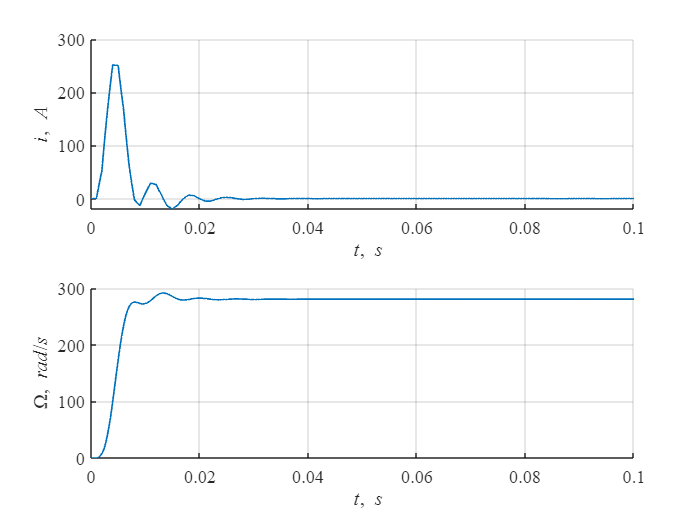

t = SimOut.i(:,1);
ic = SimOut.i(:,2);
wc = SimOut.i(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
hold on
grid on
plot(t,ic,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\iti\rm,\it A')

ax(2) = subplot(2,1,2);
hold on
grid on
plot(t,wc,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\Omega\rm,\it rad\rm/\its')

linkaxes(ax, 'x')

Время переходного процесса tp1 (5% зона)

wd = wc;

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.4f\n',ttr5)

Время переходного процесса tp1 для 5% зоны: 0.0070


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.4f\n',ttr5)

Время переходного процесса tp2 для 5% зоны: 0.0070


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.3f%%\n',dy*100)

Перерегулирование: 3.907%


Запасы по амплитуде и по фазе

ww = 10.^(-2:0.01:4);
sww = 1i*ww;

Wol_symbolic = Wtfobsp*Wsplp

$$Wol\_symbolic = \frac{{\mathrm{Cm}}_{s}\,\left(b_{2}\,s^{2}+b_{1}\,s+b_{0}\right)}{J_{s}\,s^{2}\,\left({\mathrm{Tu}}_{s}\,s+1\right)\,\left(a_{1}\,s+1\right)}$$

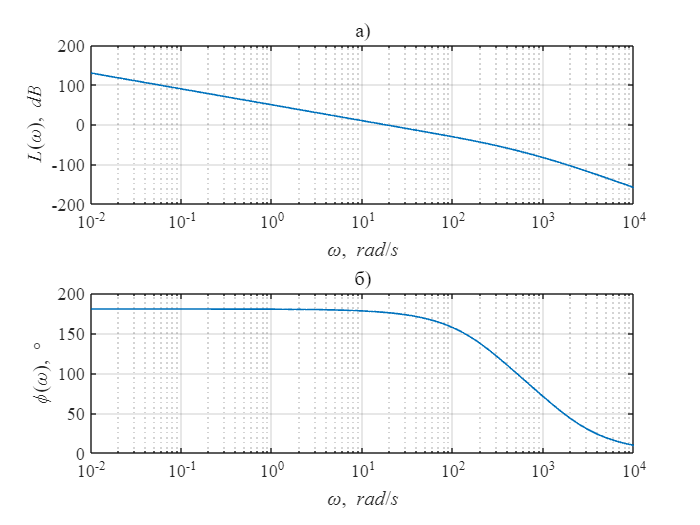

Wol_numeric = Cm./(J.*sww.^2.*(Tu.*sww + 1).*(a1.*sww + 1));

[LL, phiphi] = freqplot(ww,Wol_numeric);

Графики ЛАЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

[Lminmin, indind] = min(abs(LL));
phi_marg = phiphi(indind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),ww(indind))

Запас по фазе: 355.803° при частоте 17.378 рад/c


#### Показатель колебательности

Wcl_symbolic = collect(Wol_symbolic./(1 + Wol_symbolic),s)

$$Wcl\_symbolic = \frac{{\mathrm{Cm}}_{s}\,\left(b_{2}\,s^{2}+b_{1}\,s+b_{0}\right)}{J_{s}\,s^{2}\,\left({\mathrm{Tu}}_{s}\,s+1\right)\,\left(a_{1}\,s+1\right)\,\left(\frac{{\mathrm{Cm}}_{s}\,\left(b_{2}\,s^{2}+b_{1}\,s+b_{0}\right)}{J_{s}\,s^{2}\,\left({\mathrm{Tu}}_{s}\,s+1\right)\,\left(a_{1}\,s+1\right)}+1\right)}$$

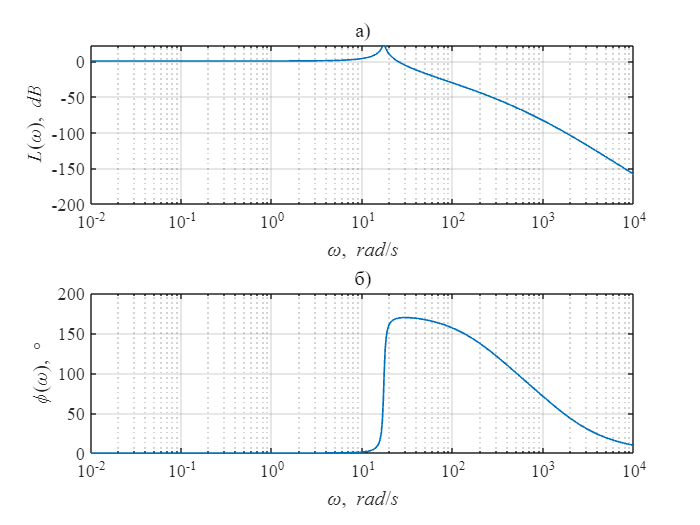

Wcl_numeric = Wol_numeric./(1 + Wol_numeric);

[LL,phiphi] = freqplot(ww,Wcl_numeric);

Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

Показатель колебательности

MM = 10^((max(LL)-LL(1))/20)/10^(LL(1)/20);
fprintf('Показатель колебательности M: %.3f \n',MM)

Показатель колебательности M: 13.164 


std(wd)

ans = 53.0003